# Intent Recognition using Vocal Recordings: Neural Network Classification based on Raw Audio Signals

**Michele Ferrari [*****21118273*****]**

**06/11/2021**

## Introduction

The task is to classify voice recordings into three different classes:

- Approval

- Prohibition

- Attention

Data come from two datasets: *Kismet* and *BabyYears*.

## 1. Data Import

Automatically import all `.wav` files and organize them in proper data structures.

clear; close all; clc
import_data_Kismet
import_data_BabyEars
clearvars

## 2. Data Visualization

Use Kismet Dataset and subject CY as an example.

load kismet_WAV.mat
load babyYears_WAV.mat

### 2.1 Display signal in the time domain

Example of the content of `.wav` files. It is the raw signal, as registered by the microphone.

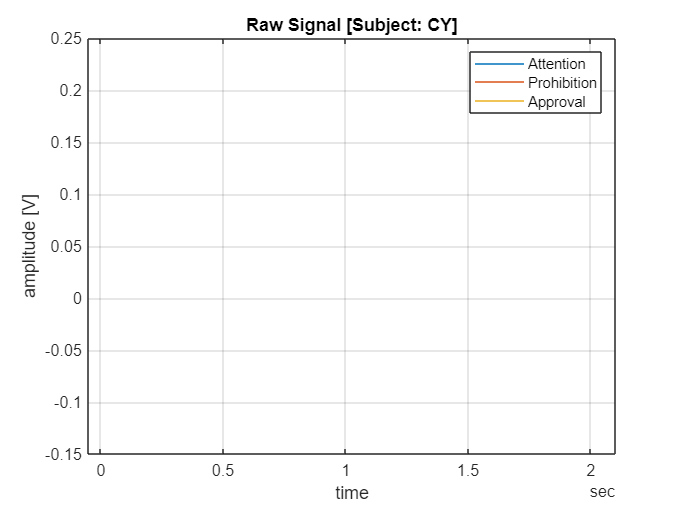

figure

data_at = kismet_WAV(1).Data;
label = kismet_WAV(1).Label;
subject = kismet_WAV(1).Subject;
plot(data_at.time, data_at.amplitude)

hold on

data_pw = kismet_WAV(5).Data;
label = kismet_WAV(5).Label;
subject = kismet_WAV(5).Subject;
plot(data_pw.time, data_pw.amplitude)

data_ap = kismet_WAV(12).Data;
label = kismet_WAV(12).Label;
subject = kismet_WAV(12).Subject;
plot(data_ap.time, data_ap.amplitude)

xlabel('time')
ylabel('amplitude [V]')
grid on
legend('Attention','Prohibition','Approval')
title(['Raw Signal [Subject: ' upper(subject) ']'])

### 2.2 Basic spectral information about the wav signal

Here the Power Spectral Density and the spectrogram of the signals are displayed, in order to show the spectral differences among different classes. These informations will be used to classifiy signals.

**Attention**

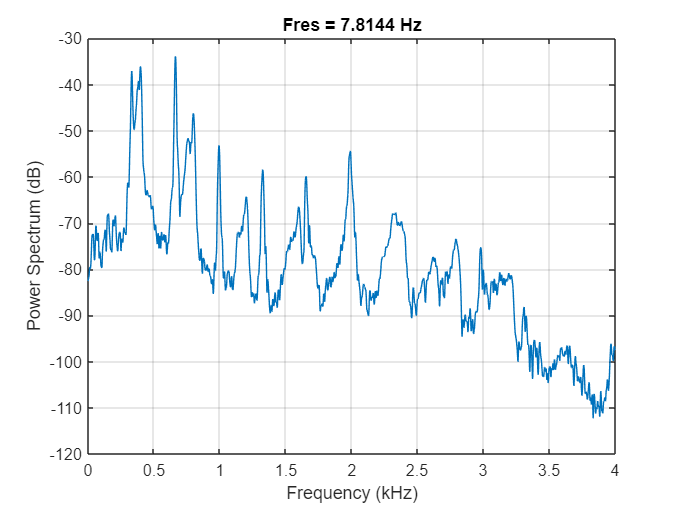

figure
show_psd_at

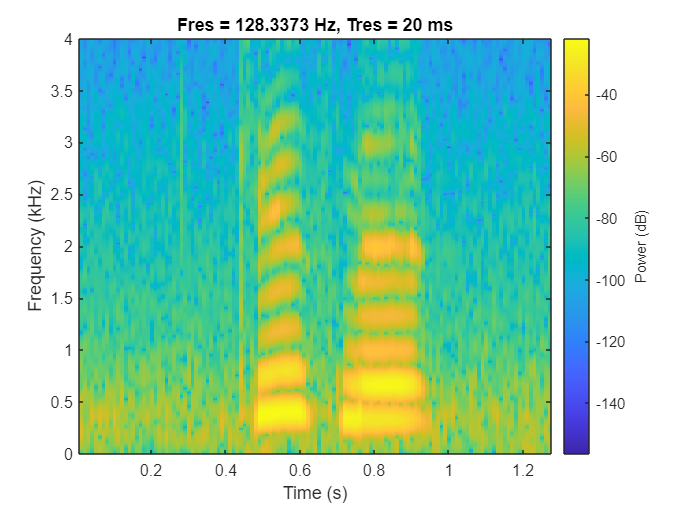

show_spectrogram_at

**Prohibition**

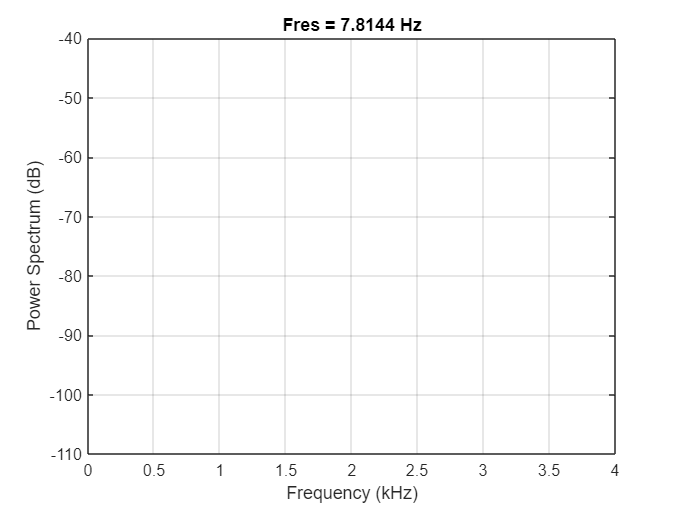

figure
show_psd_pw

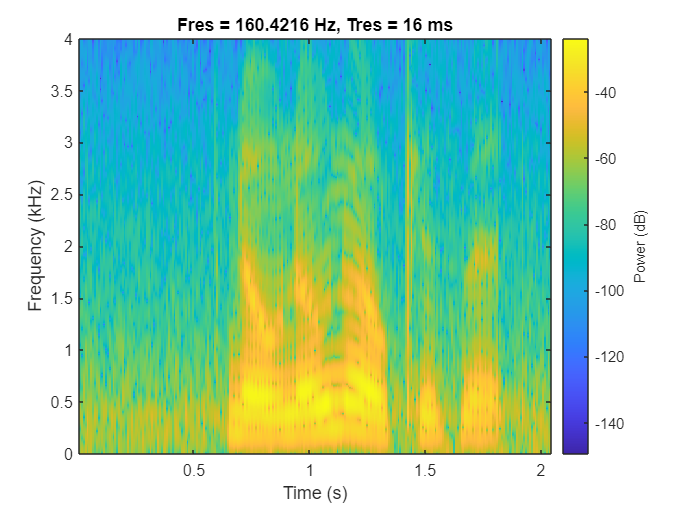

show_spectrogram_pw

**Approval**

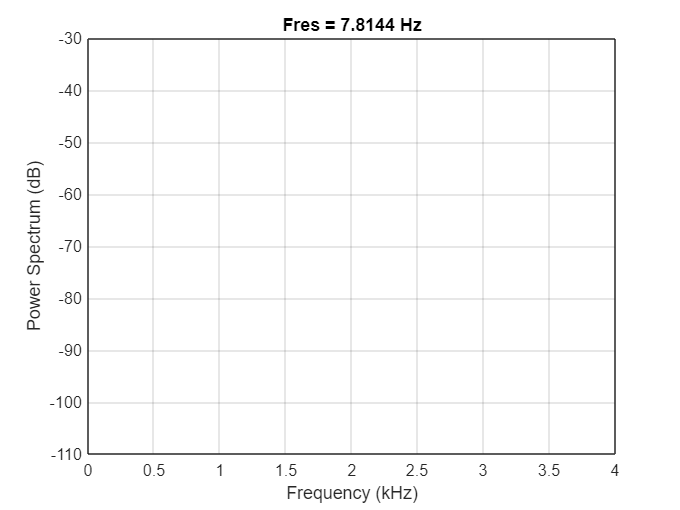

figure
show_psd_ap

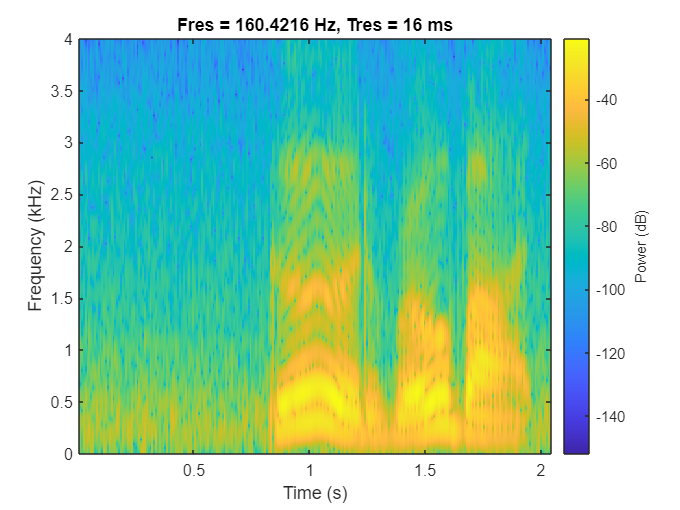

show_spectrogram_ap

### 2.3 Visualize relevant features of the audio signals

*Devopedia. 2021. "Audio Feature Extraction." Version 8, May 23. Accessed 2021-09-09. *[*https://devopedia.org/audio-feature-extraction*](https://devopedia.org/audio-feature-extraction)

data_example = {data_at.amplitude; data_pw.amplitude; data_ap.amplitude};
example = data_example{1};

% Create and set up an audioFeatureExtractor object
extractor = audioFeatureExtractor("SampleRate",kismet_fs, ...
    "SpectralDescriptorInput","melSpectrum", ...
    "melSpectrum",true,"mfcc",true, ...
    "spectralCentroid",true,"spectralCrest",true, ...
    "spectralFlatness",true,"spectralFlux",true, ...
    "spectralSkewness",true,"spectralSlope",true);

% Extract features from audio data

Removed sample #111
Removed sample #128
Removed sample #152
Removed sample #156
Removed sample #158
Removed sample #33
Removed sample #50
Removed sample #75
Removed sample #80
Removed sample #85
Removed sample #86
Removed sample #103
Removed sample #121
Removed sample #121
Removed sample #132
Removed sample #135
Removed sample #135
Removed sample #138
Removed sample #149
Removed sample #154
Removed sample #161
Removed sample #164
Removed sample #166
Removed sample #167
Removed sample #169
Removed sample #169
Removed sample #169
Removed sample #169
Removed sample #171
Removed sample #171
Removed sample #171
Removed sample #171
Removed sample #172
Removed sample #172
Removed sample #172
Removed sample #180
Removed sample #180
Removed sample #183
Removed sample #183
Removed sample #185
Removed sample #187
Removed sample #188
Removed sample #188
Removed sample #189
Removed sample #190
Removed sample #192
Removed sample #192
Removed sample #192
Removed sample #194
Removed sample #199
Remove

features2 = extract(extractor,example);

% Display output summary
info(extractor)

## 3. Signal Preprocessing

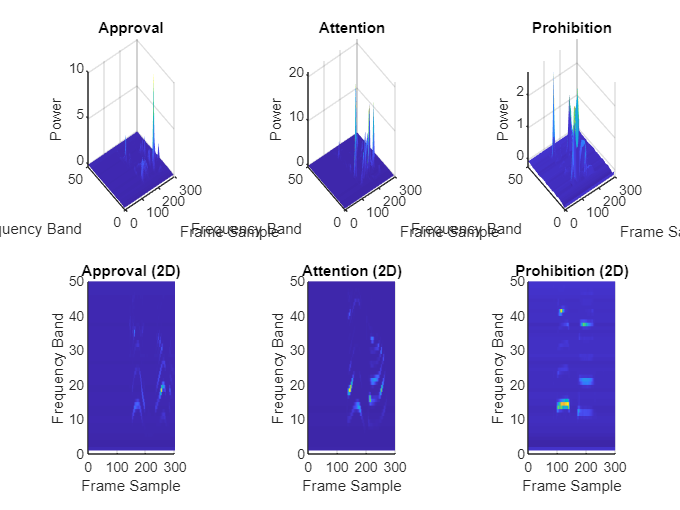

load kismet_WAV.mat
load babyYears_WAV.mat

signal_preprocessing
clearvars

## 4. Feature Extraction

load kismet.mat
load babyYears.mat

% feature_extraction
feature_extraction_spectrogram
clearvars

## 5. Training and Test Datasets, Feature Normalization and PCA

load features_kismet.mat
load features_babyYears.mat

training_percentage = 0.6;

% Select the task you want to perform
% TASK FLAG:
task_selection = "Baby_Kismet_vs_Baby";

switch task_selection

### 5.1 Intra-corpus Approach

#### 5.1.1 Train on Kismet, Test on Kismet

    case "Kismet_vs_Kismet"
        [features_train,labels_train,features_test,labels_test] = random_extraction(features_kismet,labels_kismet,training_percentage);

#### 5.1.2 Train on BabyYears, Test on BabyYears

    case "Baby_vs_Baby"
        [features_train,labels_train,features_test,labels_test] = random_extraction(features_babyYears,labels_babyYears,training_percentage);

### 5.2 Cross-corpus Approach

#### 5.2.1 Train on Kismet, Test on BabyYears

    case "Kismet_vs_Baby"
        features_train = features_kismet;
        labels_train = labels_kismet;
        features_test = features_babyYears;
        labels_test = labels_babyYears;

#### 5.2.2 Train on BabyYears, Test on Kismet

    case "Baby_vs_Kismet"
        features_train = features_babyYears;
        labels_train = labels_babyYears;
        features_test = features_kismet;
        labels_test = labels_kismet;

### 5.3 Pooling Approach

#### 5.3.1 Train on Kismet and BabyYears, Test on Kismet

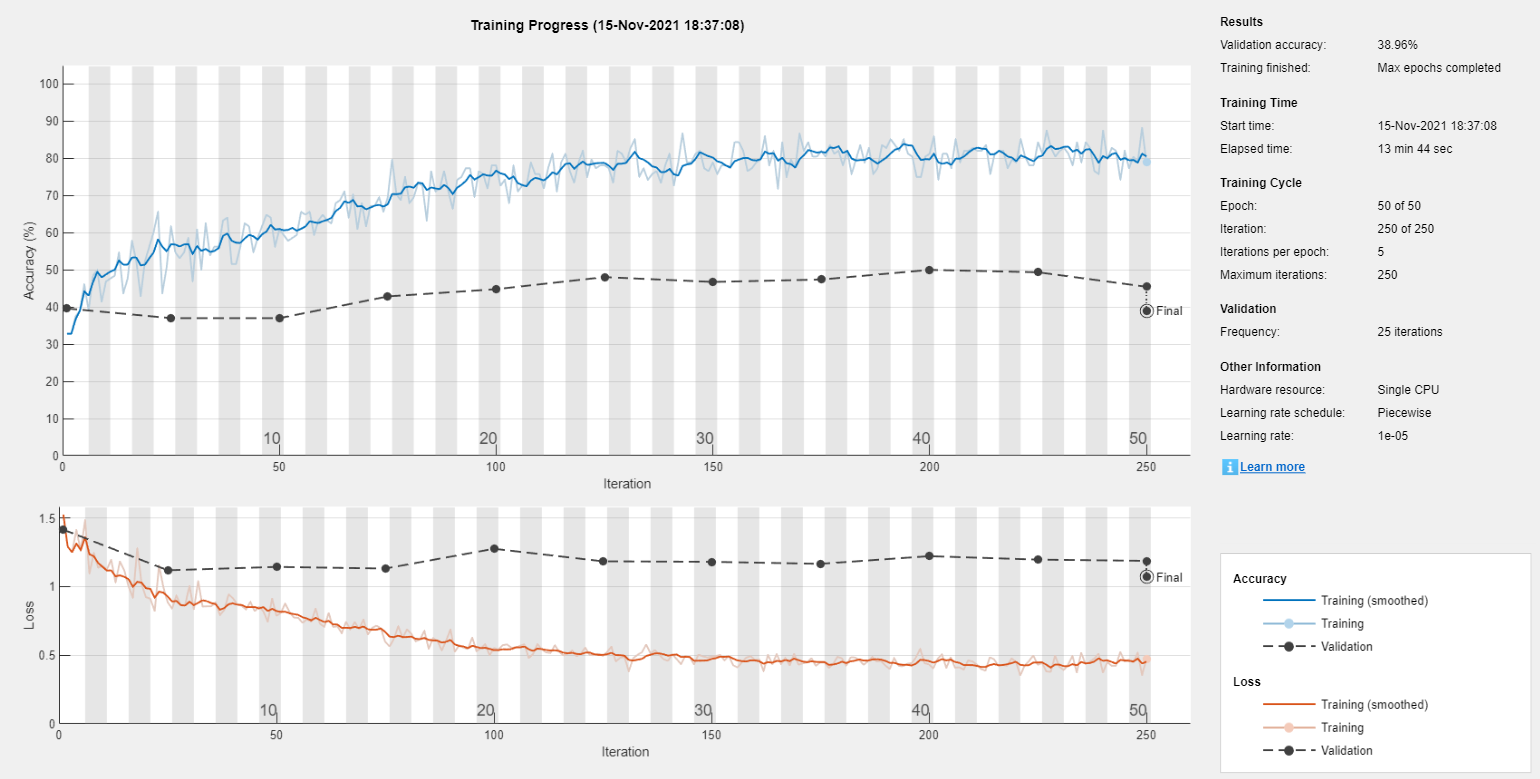

    case "Kismet_Baby_vs_Kismet"

        [features_train,labels_train,features_test,labels_test] = random_extraction(features_kismet,labels_kismet,training_percentage);
        features_train = [features_train features_babyYears];
        labels_train = [labels_train labels_babyYears];

#### 5.3.2 Train on Kismet and BabyYears, Test on BabyYears

    case "Baby_Kismet_vs_Baby"
        [features_train,labels_train,features_test,labels_test] = random_extraction(features_babyYears,labels_babyYears,training_percentage);
        features_train = [features_train features_kismet];
        labels_train = [labels_train labels_kismet];

end % End of switch statement

accuracy = 38.9610

### 5.4 Normalization

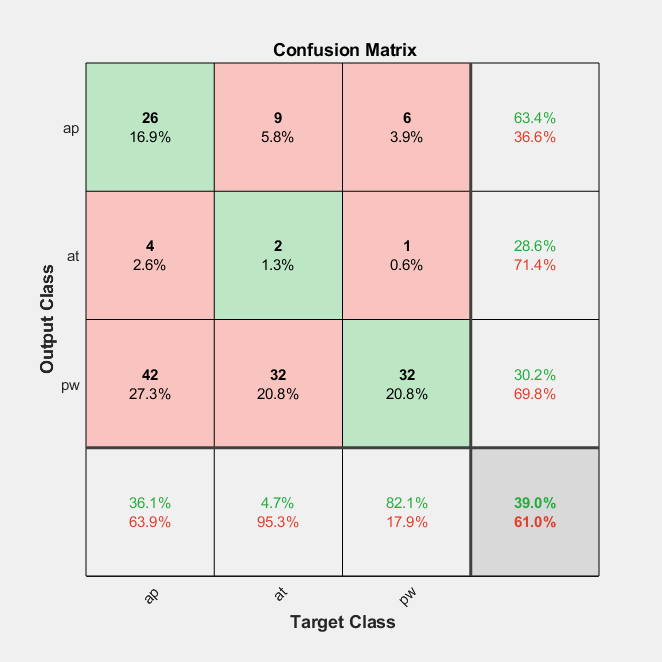

features_train_norm = normalize_features(features_train,features_train);
features_test_norm = normalize_features(features_test,features_train);

Network size: 293.5986 kB
Single-sample prediction time on CPU: 40.2931 ms
Mean accuracy: 38.2 %
Confidence Interval: [10, 70]


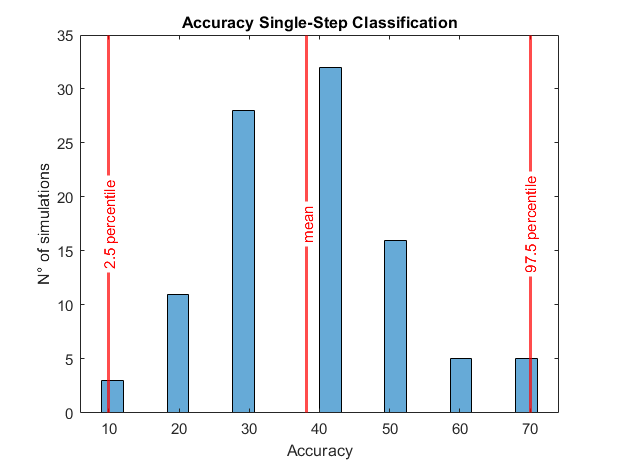


features_train = features_train_norm;
features_test = features_test_norm;


% Save features and labels to workspace
save(strcat('.\train_test_datasets\features_train_',task_selection,'.mat'),'features_train')
save(strcat('.\train_test_datasets\features_test_',task_selection,'.mat'),'features_test')
save(strcat('.\train_test_datasets\labels_train_',task_selection,'.mat'),'labels_train')
save(strcat('.\train_test_datasets\labels_test_',task_selection,'.mat'),'labels_test')

### 5.5 Principal Component Analysis

Not relevant, since we are extracting spectrograms from the audio signals and we are classifying them as images.

% num_feat = size(features_train{1},1);
% features_names = string(1:num_feat)';
% n_components = 10;
% pca_title = {'Principal Component Analysis','Kismet on Kismet Classification'};
% 
% PCA(cell2mat(features_train),pca_title,n_components,features_names);

## 6. Training of the Classifier

load(strcat('features_train_',task_selection,'.mat'))
load(strcat('features_test_',task_selection,'.mat'))
load(strcat('labels_train_',task_selection,'.mat'))
load(strcat('labels_test_',task_selection,'.mat'))
load image_dims.mat     

% network_training            % Old function that uses spectral features and classifies them as sequences
network_training_spectrogram  % Classification using image recognition of spectrograms

## 7. Validation of Classifier Accuracy (Bootstrapping)

### 7.1 Compute Validation Accuracy and Plot Confusion Matrix

load(strcat('net_',task_selection,'.mat'))

predicted_labels = classify(net,features_test);

accuracy = (sum(predicted_labels == labels_test))/length(labels_test)*100
figure
plotconfusion(labels_test,predicted_labels)

### 7.2 Evaluate Network Size, Prediction Time and Accuracy using Bootstrapping

evaluate_performance

## 8. Comparison among different Approaches

## Conclusions